# Aula 15 - Controle Integral

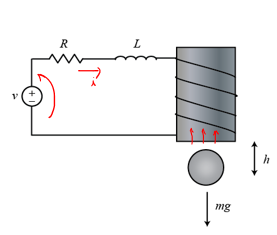

Matrizes de estado dadas:

A=[0,1,0;980, 0,-2.8;0, 0,-100];
B=[0;0;100];
C=[1,0,0];
D=0;
n=length(A)

n = 3

m=length(C)

m = 3

Por A vemos que o sistema é de terceira ordem e possui, portanto, 3 pólos. Se desejamos que o pólo $-10\pm10j$ seja dominante, devemos fazer com que o terceiro pólo seja bem distante dele.

p=[-50,-10+10j,-10-10j];

**Controle Integral:**

nova variável de estado $z=\int(y-y_d)dt$, onde $y_d$ é o setpoint.

$\dot z = y - y_d$ (erro)


$$x_e=\left\{\begin{array}{c}        x \\     z \\    \end{array}\right\}$$


1) escrever $A_{int},B_{int},C_{int}$

em malha aberta:


$$\dot x_e = \left\{\begin{array}{c}    \dot    x \\  \dot   z \\    \end{array}\right\} \left(\begin{array}{c c}  A_{nxn} & 0_{nx1} \\  C_{nx1} & 0    \end{array}\right)x_e+ \left\{\begin{array}{c}  B_{mxm} \\  0_{1xm} \end{array}\right\}u+\left\{\begin{array}{c}  0 \\  -y_d \end{array}\right\}=A_{int}x_e+B_{int}u+\left\{\begin{array}{c}  0 \\  -y_d \end{array}\right\}$$



$$y=\left\{\begin{array}{cc}  C &  0 \end{array}\right\}x_e=C_{int}x_e$$


Aint=[A,zeros(n,1);C,0];
Bint=[B;0];
Cint=[C,0];

2) Verificar controlabilidade

rank(ctrb(Aint,Bint))

ans = 4

se $rank(M_o)=n$ o sistema é observável.

3) Encontrar a matriz K

p(n+1)=-60; % adicionando mais um polo não dominante por causa da nova variável de estado
K=place(Aint,Bint,p)

K = 	1.0e+03 *

   -0.7479   -0.0228    0.0003   -2.1429


4) Escrever $A_{mf},B_{mf},C_{mf}$

em malha fechada:


$$\dot x_e = (A_{int}-B_{int}K)x_e+\left\{\begin{array}{c}  0_{nx1} \\  -1 \end{array}\right\}y_d=A_{mf}x_e+B_{mf}y_d$$



$$y=\left\{\begin{array}{cc}  C &  0 \end{array}\right\}x_e=C_{int}x_e$$


Amf=Aint-Bint*K;
Bmf=[zeros(n,1);-1];
Cmf=Cint;

5) Simular

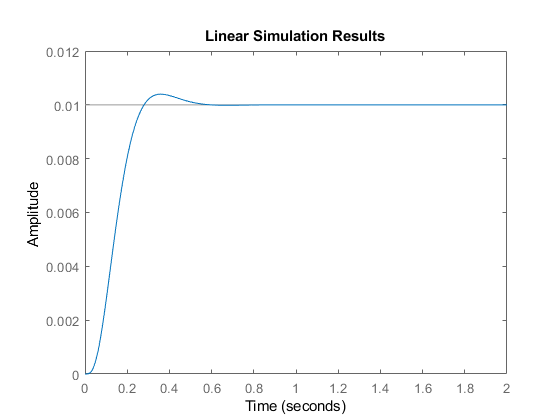

nt=1000;
t=linspace(0,2,nt);
yd=0.01*ones(nt,1); % degrau de 0.01
sys=ss(Amf,Bmf,Cmf,0);
lsim(sys,yd,t)